#                                                         

## Evaluación 2 Análisis de datos geofísicos

**Estudiante:** Valentina Iturra Rosales 2021421947

**Profesor:** 

Rodrigo Abarca del Río

**Ayudantes:**

Javier Andrade

Scarlett Moraga

Alberto Pena

Poliana Leiva

## Estadísticos móviles (30%).

clc
clear all

load('stgo_temp.mat');
TS = stgo_temp;


#### Recupere la serie stgo_t.mat y realice un cálculo de los siguientes estadísticos utilizando una ventana de 6 meses. Entregue en un gráfico todos los estadísticos sobre la serie original. (10%)

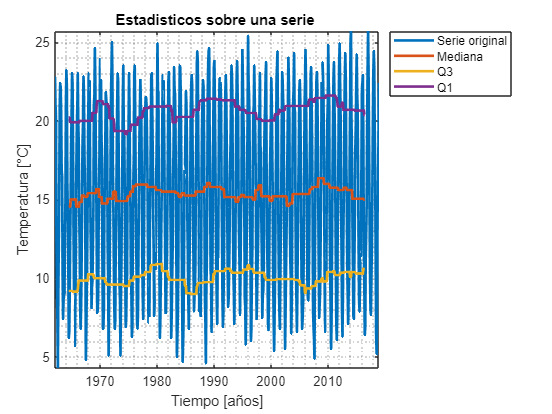

[~,~,mediana,Q1,Q3]=mmsm(TS(:,2),1,60);
tiempomovil = TS(1+29:end-30,1); 

figure()
    plot(TS(:,1),TS(:,2),'LineWidth',2)
    hold on
    plot(tiempomovil,mediana,'LineWidth',2)
    plot(tiempomovil,Q1,'LineWidth',2)
    plot(tiempomovil,Q3,'LineWidth',2)
    xlabel('Tiempo [años]')
    ylabel('Temperatura [°C]')
    axis tight
    grid minor
    legend('Serie original','Mediana','Q3','Q1','Location','bestoutside')
    title('Estadisticos sobre una serie ')

#### Transforme la serie utilizada en este ejercicio de una matriz de 684x2 a una de 57x13. 

ST_new(:,1) = [1962:2018];
for i = 1:57
    ST_new(i,2:13)= TS((12*i)-11:12*i,2);
end

#### Utilizando boxplot o histogramas realice una predicción de cómo irá variando la temperatura en los próximos años para la ciudad de Santiago

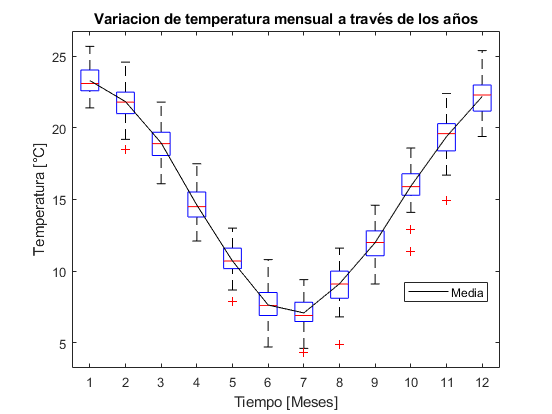

a=0;
for i = 1:12
    a= a+1;
    media(a,1) = nanmean(ST_new(1:end,i+1));
end
figure()
boxplot(ST_new(:,2:end))
hold on
plot(1:12,media,'k')
xlabel('Tiempo [Meses]')
ylabel('Temperatura [°C]')
title('Variacion de temperatura mensual a través de los años')
legend('Media','Location','best')

## 2) Filtros (40%).

#### Utilizando la misma serie anterior, con una ventana gaussiana de 6 meses y 18 meses respectivamente realice un filtro pasa alto y pasa bajo.  Presente la serie obtenida en un gráfico sobre la serie original

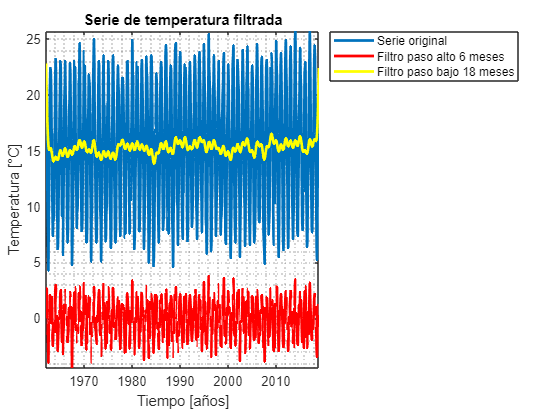


[pa_gs,~]=papb_gs(6, TS(:,2));
[~,pb_gs2]=papb_gs(18, TS(:,2));

figure()
plot(TS(:,1),TS(:,2),'LineWidth',2)
hold on
plot(TS(:,1),pa_gs,'LineWidth',2,'Color','r')
plot(TS(:,1),pb_gs2,'LineWidth',2,'Color','y')
axis tight
grid minor
xlabel('Tiempo [años]')
ylabel('Temperatura [°C]')
legend('Serie original', 'Filtro paso alto 6 meses','Filtro paso bajo 18 meses','Location','bestoutside')
title('Serie de temperatura filtrada')

#### Mediante un filtro pasa banda obtenga el ciclo estacional de la serie entregada, defina usted qué ventana considera mejor para obtener el ciclo estacional. (15%)

[filtpbd_gsa,filtpbd_gsb] = pasabanda_gs(6,3, TS(:,2));
%Para generar el ciclo estacionario se han usado dos ventanas de 3 y 6
%meses

#### Entregue en un gráfico donde se presente la serie original con el ciclo estacionario superpuesto

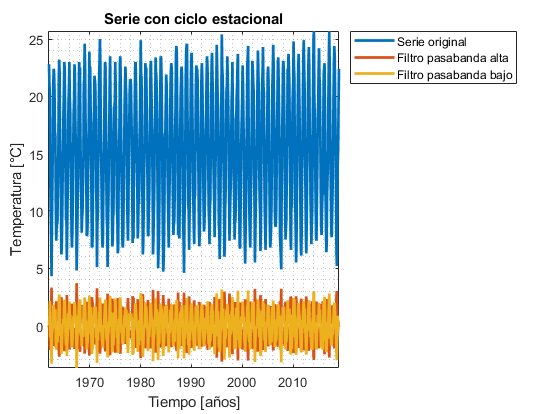

figure()
plot(TS(:,1),TS(:,2),'LineWidth',2)
hold on
plot(TS(:,1),filtpbd_gsa,'LineWidth',2)
plot(TS(:,1),filtpbd_gsb,'LineWidth',2)
axis tight
grid minor
xlabel('Tiempo [años]')
ylabel('Temperatura [°C]')
legend('Serie original', 'Filtro pasabanda alta','Filtro pasabanda bajo','Location','bestoutside')
title('Serie con ciclo estacional')

## 3) Correlaciones (30%).

#### Calcule la correlación de Pearson y Spearman utilizando las dos series de temperatura entregadas (stgo_t.mat y sr_temp.mat).

clear all
load('stgo_temp.mat')
load('sr_temp.mat') %San Rafael en Argentina

TS=stgo_temp;
TR = sr_temp;

[rho_P] = corr(TS(:,2),TR(:,2),'Type','Pearson'); 
[rho_S] = corr(TS(:,2),TR(:,2),'Type','Spearman');

#### Evalúe si la correlación obtenida es significativa considerando un nivel de confianza de 75%, 85% y 95% (solamente para la correlación de Pearson). Entregar los T_c calculados en una tabla.

[t_c1,s,alfa_med,grad_lib] = tstudent(TS(:,2),TR(:,2),75);

t_c =      1.338287966921583e+02


s =    0.007333904152146


alfa_med =    0.125000000000000


grad_lib =    682


En la tabla, 0,15 que es el más aproximado a 0,125 el valor infinito es 1.036

[t_c2,s,alfa_med,grad_lib] = tstudent(TS(:,2),TR(:,2),85);

t_c =      1.338287966921583e+02


s =    0.007333904152146


alfa_med =    0.075000000000000


grad_lib =    682


En la tabla, 0.10 que es el más aproximado a 0,075 el valor infinito es 1.645 

[t_c3,s,alfa_med,grad_lib] = tstudent(TS(:,2),TR(:,2),95);

t_c =      1.338287966921583e+02


s =    0.007333904152146


alfa_med =    0.025000000000000


grad_lib =    682


En la tabla, 0,025 el valor infinito es 1.960

Luego solo el primer T_c es significativo dado que este es mayor que el valor de tabla

tabla1 = table(t_c1,t_c2,t_c3)

tabla1 = 1×3 table
          t_c1                t_c2                t_c3      
    ________________    ________________    ________________

    133.828796692158    133.828796692158    133.828796692158


#### Realice una correlación con desfase considerando 5 años como el desfase máximo, presentar en un gráfico todas las correlaciones calculadas, además presentar la mayor correlación y su desfase correspondiente. Finalmente entregar los grados de libertad, T_c y si este es significativo para ese desfase

[r,lags] = xcorr(TS(:,2),TR(:,2),60,'normalized');
[value,posi]= max(r)

value =    0.996364755288746


posi =     61


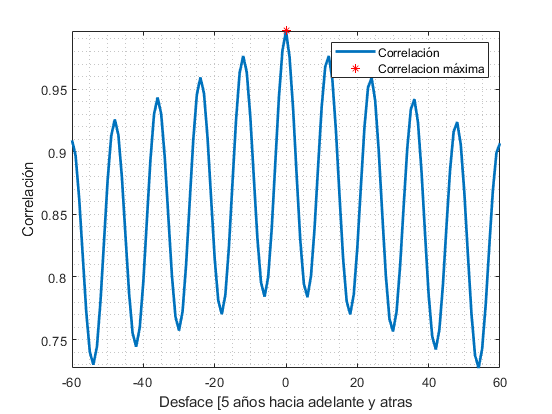

figure()
plot(lags,r,'LineWidth',2)
hold on
plot(lags(posi),value,'*r')
xlabel('Desface [5 años hacia adelante y atras')
ylabel('Correlación')
axis tight
grid minor
legend('Correlación','Correlacion máxima')

el valor del desface máximo es 

value

value =    0.996364755288746


t_c=value*sqrt((length(TS(:,2))-2)/(1-value^2)),

t_c =      3.054384951689109e+02


este valor es mayor que el de tabla entre el 0 y 99% por lo que si es  significativo

## Bonus

#### Se le es entregada 2 matrices de 144x73x366 de UwindAño.mat y VwindAño.mat, estos corresponden a componentes U y V del viento anuales. Cree una metodología usando MATLAB que le permita obtener las correlaciones entre ambas componentes. Muestre el resultado como un campo utilizando el comando contourf(5%)

clear all
load('UwindAño.mat')
load("VwindAño.mat")
a=0;
for i= 1:144
    for j = 1:73
        a=a+1;
        A(:,a)=U(i,j,:);
        B(:,a) = V(i,j,:);
    end
end
b=0;
for i = 1:9072
    b=b+1;
    rho_P(b) = corr(A(:,i),B(:,i),'Type','Pearson'); 
end

%contourf(lon,lat,rho_p)

## Anexo: Funciones utilizadas

% function [pa_gs,pb_gs]=papb_gs(ventana, datos)
% %funcion para tipo gaussiana
% 
% gs = gausswin(ventana); % de 12
% gsn = gs/sum(gs);
% 
% filt_gs = filtfilt(gsn,1,datos);
% pb_gs = filt_gs;
% 
% pasoa_gs = datos - pb_gs;
% pa_gs = pasoa_gs;
% 

% function [filtpbd_gsa,filtpbd_gsb] = pasabanda_gs(ventanaT1,ventanaT2, datos)
% 
% [pa_gsT1,pb_gsT1]=papb_gs(ventanaT1, datos);
% 
% [pa_gsT2,pb_gsT2]=papb_gs(ventanaT2, datos);
% 
% filtpbd_gsb = pb_gsT2 - pb_gsT1;
% filtpbd_gsa = pa_gsT2 - pa_gsT1;

% function [t_c,s,alfa_med,grad_lib] = tstudent(datos1,datos2,confianza)
% 
% 
% N=length(datos1);
% 
% a = corr(datos1,datos2);  %Correlacion de dos bases de datos
% t_a=a*sqrt(N-2)/sqrt(1-a^2); %Valor de t_c
% s_a=a/t_a; %Valor de s
% 
% conf=confianza;
% alpha = 1 - (conf/100);
% alpha_medios = alpha/2;
% 
% b = N-2;
% 
% t_c=t_a
% s=s_a
% alfa_med = alpha_medios
% grad_lib = b

% function [mm,dem,mediana,Q1,Q3]=mmsm(x,paso,w)
% %considerar que x corresponde a los datos, paso es cada cuanto se toman los
% %datos y w es la ventana
% c=0; 
% for i=w:paso:length(x) 
%     mm(c+1)=nanmean(x(i-w+1:i)); % media movil
%     sm(c+1)=nanstd(x(i-w+1:i)); % std movil
%     mediana(c+1)=median(x(i-w+1:i),'omitnan'); % media movil
%     Q3(c+1) = prctile(x(i-w+1:i),75);
%     Q1(c+1) = prctile(x(i-w+1:i),25);
%     c=c+1;
% end
% 
% mm=mm'; %La comilla encima representa que se traspone la matriz
% dem=sm';
% mediana = mediana;
% 
% end